# Betweeness centrality analysis kanika meeting 2

Created the following figures and analysis for the second meeting with kanika. see 

- compare temporal evolution of metrics within frequency bands and tasks, i.e., reproduce figures 1 and S1 from the paper for the rest of the tasks. For this, compare all the time points within one frequency band and task (e.g., not just baseline and t1,t2, etc.)

- compare tasks for baseline and first time point only after waking up, within specific frequency bands.

- compare baseline, t1_control, and t1_light for each frequency band and task separately (reproduce figures 2 and S2 from the paper for the rest of the tasks).

still need to create a readme from this run me file

see the main readme for details of this analysis

# Generate Master Data Set

First retreive Master Data Set

DF = dfmaster;


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done

Getting GPSD during KDT Task. . . . . . . . . . . -done

Getting Network Props during KDT: . . . . . . . . . . . -done

Getting GPSD during MATH Task. . . . . . . . . . . . -done

Getting Network Props during MATH: . . . . . . . . . . . . -done

Getting GPSD during GONOGO Task. . . . . . . . . . . . -done

Getting Network Props during GONOGO: . . . . . . . . . . . . -done


desired_ntwprop = 'clust';

# 1. Reproduce figures 1 and S1 from the paper for the rest of the tasks

Initialize Constants

clearvars -except DF desired_ntwprop
df_grp = grpAndCleanDf(DF, {'cogtest_order', 'condition', 'run', 'band_ord', 'sbj'}, desired_ntwprop, removetask={'KDT', 'Math'});


Math Task AND KDT task are removed from this data frame


Visualize

---------------------------------------------


clust during PVT TASK # # # # # # # #


## control #######

	- delta 


		Baseline VS control run 1 * SIGNIFICANT!!!


		control run 1 VS run 2 * SIGNIFICANT (p=0.001 | ni=11, nj=11)
		control run 1 VS run 3 * SIGNIFICANT (p=0.000 | ni=11, nj=11)


	- theta 
	- alpha 
	- beta 


		control run 1 VS run 3 * SIGNIFICANT (p=0.043 | ni=11, nj=11)


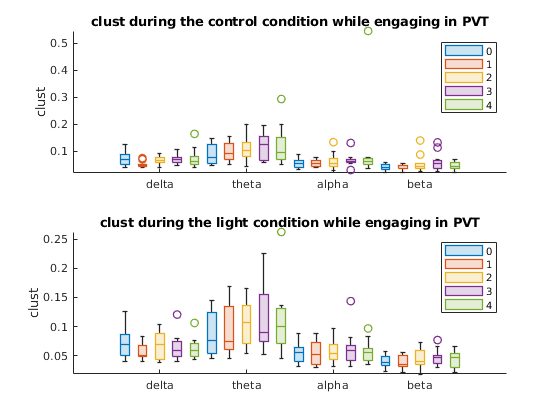

## light #######

	- delta 


		Baseline VS light run 1 * SIGNIFICANT!!!


	- theta 
	- alpha 
	- beta 


---------------------------------------------


clust during GoNogo TASK # # # # # # # #


## control #######

	- delta 
	- theta 
	- alpha 


		Baseline VS control run 2 * SIGNIFICANT!!!


	- beta 


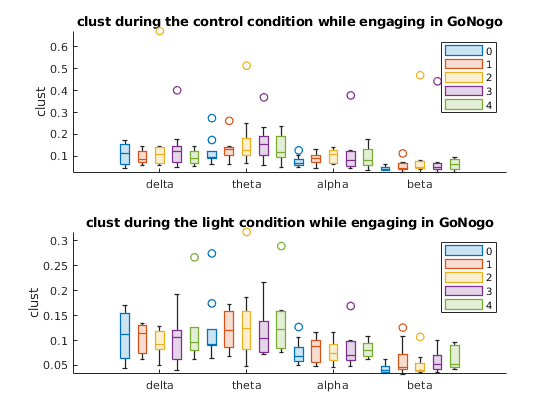

## light #######

	- delta 
	- theta 
	- alpha 
	- beta 


		Baseline VS light run 3 * SIGNIFICANT!!!
		Baseline VS light run 4 * SIGNIFICANT!!!


cogtask_list    = unique(df_grp.cogtest_order);
condition_list  = {'control', 'light'}; 
band_list       = unique(df_grp.band_ord);
runpair_list   = nchoosek(1:4, 2);

close all
for task_idx = 1:numel(cogtask_list)
    figure;
    cogtask = cogtask_list(task_idx);        
    fprintf('---------------------------------------------\n')
    fprintf('%s during %s TASK # # # # # # # #\n', desired_ntwprop, cogtask)
    
    % For either the control or the light condition 
    for cond_idx = 1:2
        desired_condition = condition_list{cond_idx};

        df_grp_task = df_grp(df_grp.cogtest_order == cogtask & (df_grp.condition == desired_condition | df_grp.condition == 'baseline'),: );
        
        ax = nexttile;
        boxchart(df_grp_task.band_ord, df_grp_task.mean_Y, 'GroupByColor',df_grp_task.run);
        infostr = sprintf('%s during the %s condition while engaging in %s', desired_ntwprop, desired_condition, cogtask);
        ylabel(desired_ntwprop);

        title(infostr);
        axis tight
        legend
        drawnow;            
        fprintf('## %s #######', desired_condition)  

        % For one of the 4 fs bands
        for band_idx = 1:4
            band_name = band_list(band_idx);
            fprintf('\t- %s \n', band_name) 

            df_bl_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == 'baseline') & (df_grp.band_ord == band_name) ;
            df_bl       = df_grp(df_bl_rowidx,:); 
            for run_j = 1:4
                df_cntl_r1_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == run_j);
                df_cntl_r1 = df_grp(df_cntl_r1_rowidx,:);                                
                [h_bl_vs_cntl,P,CI,STATS] = ttest(df_bl.mean_Y,df_cntl_r1.mean_Y);
                if h_bl_vs_cntl == 1
                    fprintf('\t\tBaseline VS %s run %d * SIGNIFICANT!!!\n', desired_condition, run_j);
                end
            end
            
            % Compare pairs of runs (including baseline)
            for runpair_idx = 1:6
                run_i = runpair_list(runpair_idx,1);
                run_j = runpair_list(runpair_idx,2); 

                df_run_i_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == run_i);
                df_run_i        = df_grp(df_run_i_rowidx,:);

                df_run_j_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == run_j);
                df_run_j        = df_grp(df_run_j_rowidx,:);

                [h_bl_vs_cntl,P,CI,STATS] = ttest(df_run_i.mean_Y,df_run_j.mean_Y);
                if h_bl_vs_cntl == 1
                    fprintf('\t\t%s run %d VS run %d * SIGNIFICANT (p=%.03f | ni=%d, nj=%d)\n', desired_condition, run_i, run_j, P, height(df_run_i), height(df_run_j));
                end
            end
        end
    
    end
end

# 2. compare PAIRS of tasks for baseline and first time point only after waking up, within specific frequency bands.

Initialize Constants

clearvars -except DF desired_ntwprop
df_grp = grpAndCleanDf(DF, {'cogtest_order', 'condition', 'run', 'band_ord', 'sbj'}, desired_ntwprop,removetask={'KDT', 'Math'});


Math Task AND KDT task are removed from this data frame


Visualize

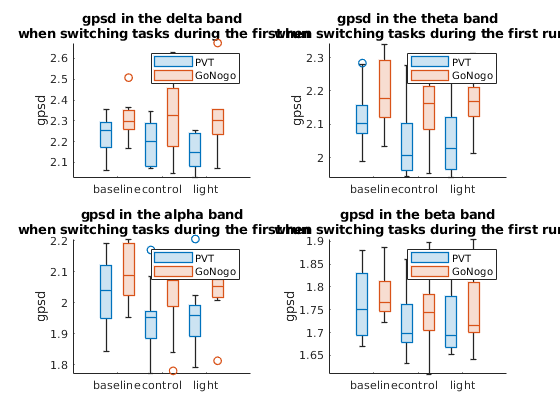

---------------------------------------------


	## delta BAND BASELINE, CONTROL AND LIGHT RUN 1##


---------------------------------------------


	## theta BAND BASELINE, CONTROL AND LIGHT RUN 1##


---------------------------------------------


	## alpha BAND BASELINE, CONTROL AND LIGHT RUN 1##


---------------------------------------------


	## beta BAND BASELINE, CONTROL AND LIGHT RUN 1##


band_list       = unique(df_grp.band_ord);
figure;
for band_idx = 1:4
    band_name = band_list(band_idx);
    fprintf('---------------------------------------------\n')        
    fprintf('\t## %s BAND BASELINE, CONTROL AND LIGHT RUN 1##\n', upper(band_name)); 
    
    df_plot_bl = df_grp(df_grp.band_ord == band_name & df_grp.condition == 'baseline' &  df_grp.run == 0,:); 
    df_plot_r1 = df_grp(df_grp.band_ord == band_name  & df_grp.run == 1,:); 
    df_plot_bl_r1 = [df_plot_bl;df_plot_r1];
    
    ax = nexttile;
    boxchart(df_plot_bl_r1.condition, df_plot_bl_r1.mean_Y, 'GroupByColor',df_plot_bl_r1.cogtest_order);
    infostr = sprintf('%s in the %s band\n when switching tasks during the first run', desired_ntwprop, band_name);
    ylabel(desired_ntwprop);
    axis tight
    title(infostr)
    legend;
    drawnow;           
end

TEST

cogtask_list = unique(df_grp.cogtest_order);
condition_list = {'baseline', 'control', 'light'}; 
band_list       = unique(df_grp.band_ord);
taskpair_list = nchoosek(1:numel(cogtask_list), 2);

for band_idx = 1:4
    band_name = band_list(band_idx);
    fprintf('---------------------------------------------\n')  
    fprintf('## %s ##\n', band_name);     
    
    for cond_idx = 1:3
        desired_condition = condition_list{cond_idx};
        fprintf('\t%s condition first run \n', upper(desired_condition))
        for taskpair_idx = 1:size(taskpair_list,1)
            task_i_idx = taskpair_list(taskpair_idx,1);
            task_j_idx = taskpair_list(taskpair_idx,2);
            task_i = cogtask_list(task_i_idx);
            task_j = cogtask_list(task_j_idx);
            
            % Test
            if strcmp(desired_condition, 'baseline')
                runidx = 0;
            else
                runidx = 1;
            end
            df_i_rowidx = (df_grp.cogtest_order == task_i) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == runidx) ;
            df_j_rowidx = (df_grp.cogtest_order == task_j) & (df_grp.condition == desired_condition) & (df_grp.band_ord == band_name) & (df_grp.run == runidx) ;

            df_i = df_grp(df_i_rowidx,:);
            df_j = df_grp(df_j_rowidx,:);
            
            [h,P,CI,STATS] = ttest2(df_i.mean_Y,df_j.mean_Y);
            if h == 1
                fprintf('\t\t%s vs %s is SIGNIFICANT (p=%.03f|ni=%d|nj=%d )\n', task_i, task_j,P, height(df_i), height(df_j))
            else
                fprintf('\t\t%s vs %s is n.s.\n', task_i, task_j)
            end
                           

        end
    end
end

---------------------------------------------


## delta ##


	BASELINE condition first run 


		PVT vs GoNogo is n.s.


	CONTROL condition first run 


		PVT vs GoNogo is n.s.


	LIGHT condition first run 


		PVT vs GoNogo is n.s.


---------------------------------------------


## theta ##


	BASELINE condition first run 


		PVT vs GoNogo is n.s.


	CONTROL condition first run 


		PVT vs GoNogo is n.s.


	LIGHT condition first run 


		PVT vs GoNogo is SIGNIFICANT (p=0.011|ni=11|nj=9 )


---------------------------------------------


## alpha ##


	BASELINE condition first run 


		PVT vs GoNogo is n.s.


	CONTROL condition first run 


		PVT vs GoNogo is n.s.


	LIGHT condition first run 


		PVT vs GoNogo is n.s.


---------------------------------------------


## beta ##


	BASELINE condition first run 


		PVT vs GoNogo is n.s.


	CONTROL condition first run 


		PVT vs GoNogo is n.s.


	LIGHT condition first run 


		PVT vs GoNogo is n.s.


# 3.  Reproduce figures 2 and S2 from the paper for the rest of the tasks

clearvars -except DF desired_ntwprop
df_grp = grpAndCleanDf(DF, {'cogtest_order', 'condition', 'run', 'band_ord', 'sbj'}, desired_ntwprop, removetask = {'KDT', 'Math'});


Math Task AND KDT task are removed from this data frame


VISUALIZE

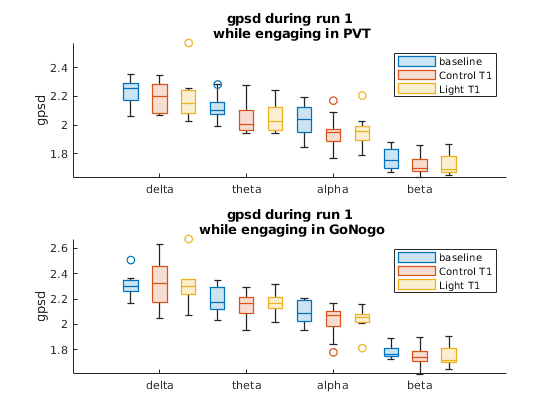

cogtask_list = unique(df_grp.cogtest_order);
close all

figure;    
for taskidx = 1:numel(cogtask_list)
    cogtask = cogtask_list(taskidx);   
    df_plot_bl = df_grp(df_grp.cogtest_order == cogtask & df_grp.condition == 'baseline',:); 
    df_plot_r1 = df_grp(df_grp.cogtest_order == cogtask & df_grp.run == 1,:); 
    df_plot_bl_r1 = [df_plot_bl;df_plot_r1];
    
    
    ax = nexttile;
    boxchart(df_plot_bl_r1.band_ord, df_plot_bl_r1.mean_Y, 'GroupByColor',df_plot_bl_r1.condition);
    infostr = sprintf('%s during run 1\n while engaging in %s', desired_ntwprop, cogtask);
    ylabel(desired_ntwprop);
    title(infostr);
    axis tight
    drawnow;           
    legend
    legend({'baseline','Control T1', 'Light T1'});
drawnow    

end

Test

condition_list = {'control', 'light'}; 
band_list       = unique(df_grp.band_ord);

for taskpair_idx = 1:numel(cogtask_list)
    cogtask = cogtask_list(taskpair_idx); 
    fprintf('---------------------------------------------\n')        
    fprintf('## %s %s ##', cogtask, desired_ntwprop)   
    for band_idx = 1:4
        band_name = band_list(band_idx);
        fprintf('\t### %s ###\n', band_name) 

        % Test
        df_bl_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == 'baseline') & (df_grp.band_ord == band_name) ;
        df_bl           = df_grp(df_bl_rowidx,:); 

        df_cntl_r1_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == 'control') & (df_grp.band_ord == band_name) & (df_grp.run == 1);
        df_cntl_r1 = df_grp(df_cntl_r1_rowidx,:); 

        df_light_r1_rowidx = (df_grp.cogtest_order == cogtask) & (df_grp.condition == 'light') & (df_grp.band_ord == band_name) & (df_grp.run == 1);
        df_light_r1 = df_grp(df_light_r1_rowidx,:);             

        [h_bl_vs_cntl, p_cntl] = ttest(df_bl.mean_Y,df_cntl_r1.mean_Y);
        [h_bl_vs_light,p_light] = ttest(df_bl.mean_Y,df_light_r1.mean_Y);
        [h_cntl_vs_light,p_cntl_vs_light] = ttest(df_cntl_r1.mean_Y,df_light_r1.mean_Y);
        

        if h_bl_vs_cntl == 1
            fprintf('\t\t - bl VS control run 1 * SIGNIFICANT (p=%.03f |Nbl=%d , Ncntl = %d)\n',p_cntl, height(df_bl), height(df_cntl_r1));            
        end

        if h_bl_vs_light == 1
            fprintf('\t\t - bl VS Light run 1 * SIGNIFICANT (p=%.03f |Nbl=%d , Nlight = %d)\n',p_light, height(df_bl), height(df_light_r1));            
        end

        if h_cntl_vs_light == 1
            fprintf('\t\t - Control run1 VS Light run 1 * SIGNIFICANT (p=%.03f |Ncntl=%d , Nlight = %d)\n',p_cntl_vs_light, height(p_cntl_vs_light), height(df_light_r1));            
        end        


    end


end

---------------------------------------------


## PVT gpsd ##

	### delta ###
	### theta ###
	### alpha ###


		 - bl VS control run 1 * SIGNIFICANT (p=0.003 |Nbl=11 , Ncntl = 11)


		 - bl VS Light run 1 * SIGNIFICANT (p=0.011 |Nbl=11 , Nlight = 11)


	### beta ###


		 - bl VS control run 1 * SIGNIFICANT (p=0.006 |Nbl=11 , Ncntl = 11)


		 - bl VS Light run 1 * SIGNIFICANT (p=0.009 |Nbl=11 , Nlight = 11)


---------------------------------------------


## GoNogo gpsd ##

	### delta ###
	### theta ###
	### alpha ###


		 - bl VS control run 1 * SIGNIFICANT (p=0.035 |Nbl=9 , Ncntl = 9)


		 - bl VS Light run 1 * SIGNIFICANT (p=0.020 |Nbl=9 , Nlight = 9)


	### beta ###


		 - bl VS control run 1 * SIGNIFICANT (p=0.025 |Nbl=9 , Ncntl = 9)


		 - bl VS Light run 1 * SIGNIFICANT (p=0.030 |Nbl=9 , Nlight = 9)


# Functions

### Extract subset of master data frame and average accross channels, bands and subjects

function df_grouped = grpAndCleanDf(DF, groupingvars, desired_ntwprop, opts)
    arguments
        DF
        groupingvars
        desired_ntwprop 
        opts.removetask = 'None';
    end
    extdf = @(cogtask, ntw, sbj) DF( ((DF.cogtest_order == cogtask)) & any((DF.ntwprop == ntw),2)  &  ismember(DF.sbj, sbj),:);
    df_pvt      = extdf('PVT', desired_ntwprop, goodsbj('PVT'));
    df_gonogo   = extdf('GoNogo', desired_ntwprop, goodsbj('GoNogo'));    
    df_kdt      = extdf('KDT', desired_ntwprop, goodsbj('KDT'));
    df_math   = extdf('Math', desired_ntwprop, goodsbj('Math'));     
    
    if ~all(ismember(opts.removetask, {'None', 'Math', 'KDT'}))
        error('LUIS: you are only allowed to remove the Math task or KDT (case sensitive');
    end

    if ismember({'NONE'}, opts.removetask)
        df = [df_pvt;df_gonogo; df_math; df_kdt];
        fprintf('\nAll Tasks will be concatenated in this data frame\n') 

    elseif all(ismember({'Math', 'KDT'},opts.removetask))
        df = [df_pvt;df_gonogo];
        fprintf('\nMath Task AND KDT task are removed from this data frame\n')                     
    elseif ismember({'Math'},opts.removetask)
        df = [df_pvt;df_gonogo; df_kdt];       
        fprintf('\nMath Task task is removed from this data frame\n')     
    elseif ismember({'KDT'},opts.removetask)  
        df = [df_pvt;df_gonogo; df_math];
        fprintf('\nKDT Task task is removed from this data frame\n')     
    end



    df_grouped = varfun(@mean, df, "InputVariables","Y","GroupingVariables",groupingvars);
    df_grouped = dfrmcats(df_grouped);

end